# On love and research software: Sharing code with your Valentine

[ ](https://matlab.mathworks.com/open/github/v1?repo=mathworks/matlab-blog&file=2025/Valentine/valentines2025.mlx)

I've been sharing mathematical equations with some sort of connection to Valentine's day for a long time now. Indeed, the first time I did it was [17 years ago](https://walkingrandomly.com/?p=59) on my old WalkingRandomly blog and I've repeated variations of this several time since. It's a very obvious social media post to make for a technical computing blogger at this time of year. Here's the plan:

- Find some equations that, when plotted, look like a 2D or 3D heart or, alternatively, flowers.

- Write the code that makes a pretty plot from these equations, maybe even animate it

- Publish it, ideally around Valentine's day

- Share the code in a form that allows other people to use it and make their own variations

Like this, [taken from the 2023 MATLAB Online MiniHack](https://uk.mathworks.com/matlabcentral/communitycontests/contests/6/entries/12797)

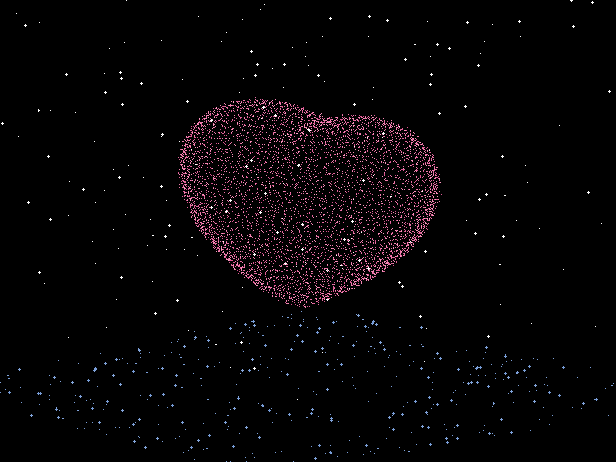

generateRotatingHeart(96); % Generate 96 frames of the rotating heart

The way I've shared these codes has evolved over the years. In my early WalkingRandomly posts, I didn't include the code at all! The post was essentially an advert of what I did, little more than a screenshot of a graph along with some mathematics. In later years, I included code listings that the reader could copy and paste. Here's a programmatic rose, for example, that you can copy and paste from this post into your MATLAB.

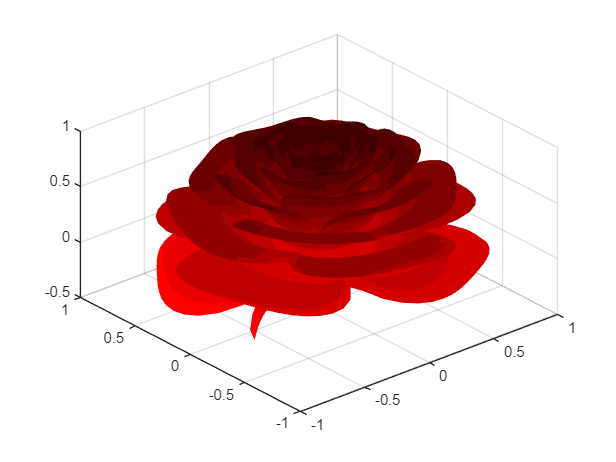

figure
n = 800;
A = 1.995653;
B = 1.27689;
C = 8;
r=linspace(0,1,n);
theta=linspace(-2,20*pi,n);
[R,THETA]=ndgrid(r,theta);
% define the number of petals we want per cycle. Roses have 3 and a bit.
petalNum=3.6;
x = 1 - (1/2)*((5/4)*(1 - mod(petalNum*THETA, 2*pi)/pi).^2 - 1/4).^2;
phi = (pi/2)*exp(-THETA/(C*pi));
y = A*(R.^2).*(B*R - 1).^2.*sin(phi);
R2 = x.*(R.*sin(phi) + y.*cos(phi));
X=R2.*sin(THETA);
Y=R2.*cos(THETA);
Z=x.*(R.*cos(phi)-y.*sin(phi));
% % define a red map for our rose colouring
red_map = linspace(1,0.25,10)' .* [1 0 0];
surf(X,Y,Z,'LineStyle','none')
view([-40.50 42.00])
colormap(red_map)

## On love and research software

While writing this post I reflected on the fact that my personal evolution for sharing code representing hearts and flowers is very similar to the evolution of how code has been shared in computational research papers over the years. How many times have you seen something like this in a research paper?

*"Our analysis was performed by a custom MATLAB script"*

Whenever I read that I just *know *that I'm unlikely to ever see that script. The paper was an advertisement for the work that was done, just like my old blog posts that showed a heart but didn't share the code that went along with it. 

Papers that include the script as an appendix are a step in the right direction but then you have the problem of getting the code from the paper and into your machine. 'Just copy and paste' sounds easy but there are often issues with formatting. Computer code can get mangled by software that tries to nicely typeset it, doing strange things to important elements such as quotation marks. For a Valentine's example, I needed to look no further than our own social media team who were having a problem with some code they had found online.

[This reddit post](https://www.reddit.com/r/matlab/comments/1eq66kc/made_a_heart_on_matlab/) included a great animation of a heart generated by a MATLAB script. This MATLAB script in fact: 

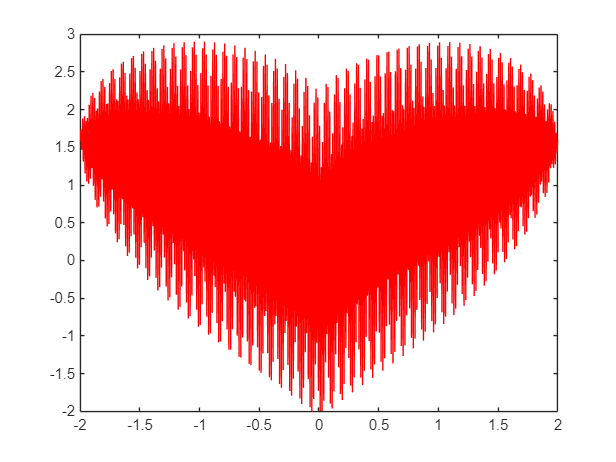

figure
a = 0:5:1700;
x = -2:0.005:2;
y = zeros(size(x));
h = plot(x, y, 'r');
axis([-2 2 -2 3]);
for i = a
    y = nthroot(x,3).^2 + 1.1.*sin(i*x).*sqrt(4-x.*x);
    set(h, 'YData', y);
    pause(0.1);
end

The author of the post had included the code but hadn't put it into a code block so the forum software mangled it, interpreting asterisks as Markdown for Italics, for example. The code needed to be fixed before it could be used again.

## The best way to share your code - for your Valentine and for your research

Over a decade ago, I delivered the [first version of a presentation called 'Is your Research Software Correct'](https://mikecroucher.github.io/MLPM_talk/) and I have since delivered variations of it perhaps more than a hundred times to thousands of researchers across the UK and Europe. Even today I get requests to dust it down and deliver it to new audiences and t contains some simple advice for anyone who is doing research that involves computation.

Two pieces of advice from that talk are **'Use version control'** and **'Share your code'**. Do that and many things will be better!

Taking my own advice, I've put the Live Script used to create this post on GitHub alongside the .m files for all of the examples shown above. This being MATLAB, however, there's something else I can do. Did you notice this badge at the top of the blog post?

[ ](https://matlab.mathworks.com/open/github/v1?repo=mathworks/matlab-blog&file=2025/Valentine/valentines2025.mlx)

If you click on that then it will **clone** the repository to your MATLAB drive, giving you your own copy of everything and it will also **open** it in MATLAB online **allowing you to** **run everything**. I haven't just shared my code with you, I've given you the means to modify and run it yourself without even needing to install MATLAB.

You can do this with your own code of course. The workflow is described in my post [Open science and reusable research with MATLAB Online and GitHub](https://blogs.mathworks.com/matlab/2023/07/20/open-science-and-reusable-research-with-matlab-online-and-github/)